# DSP Project 1 - Part 2

#### Filter a Noisy Quail Call signal using a band stop filter 

#### Retrieve the time domain,spectrogram, and fft graphs of the original signal and the filtered signal

#### Group Members:

- Farshad Bolouri

- Brennae Stinson

- Anindita Das

clear
close all

% Variables for spectrogram function
F = 1000:10:3200;
window = 24000*0.04;
noverlap = round(0.8*window);

### Loading and Visualzing the original noisy signal

[noisySig, fs] = audioread('noisySig.wav');
info = audioinfo('noisySig.wav')

info = struct with fields:
             Filename: 'C:\Users\farsh\Documents\MATLAB\DSP\DSP_Part2_FilteringCode\noisySig.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240001
             Duration: 10.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


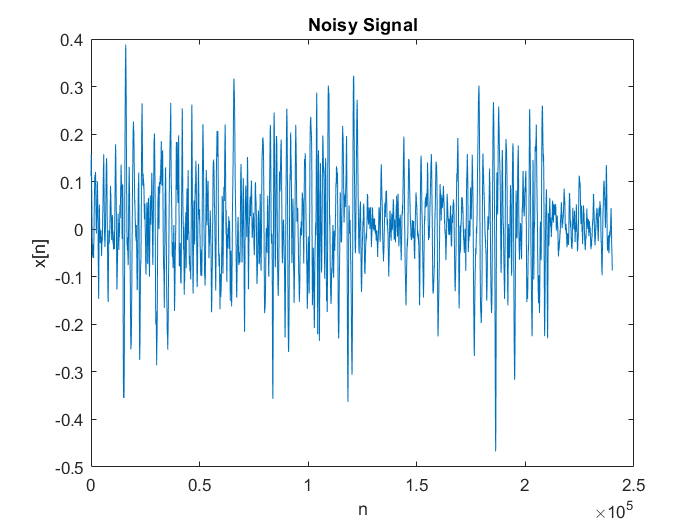

figure
plot(noisySig)
title('Noisy Signal')
xlabel('n')
ylabel('x[n]')

As you can clearly see, it is very difficult to tell that there are any quail calls present in the signal.

Now let's listen to this signal:

*(If you would prefer to not listen to this audio file, don't run this section or comment it out :) )*

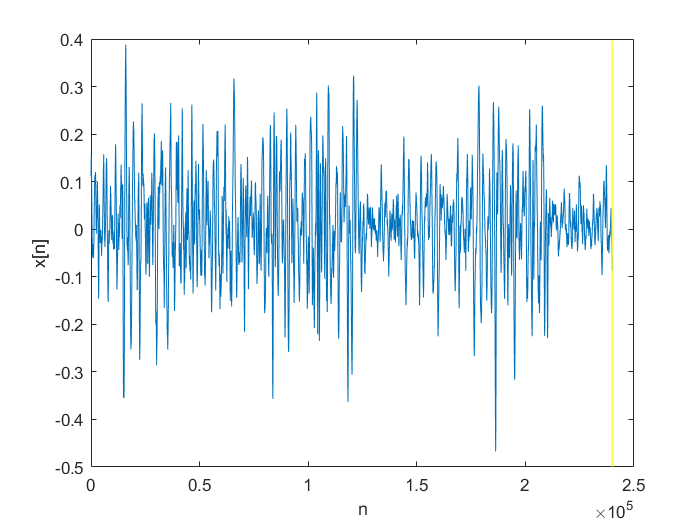

player = audioplayer(noisySig,fs);
figure
plot(noisySig)
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player);
for i = 1:length(noisySig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

As demonstrated here, you can hear the calls but with a lot of noise.

**This noise however, is present in all the audio files within the dataset. This is simply a background noise that you can always hear when you are recording in the fields. **The cause is unknown but it could be due to wind.

**The reason we cannot see the calls in the audio file is due to quails being far away from the microphone.**

Here's another signal with the same background noise (minutes after the previous signal was recorded):

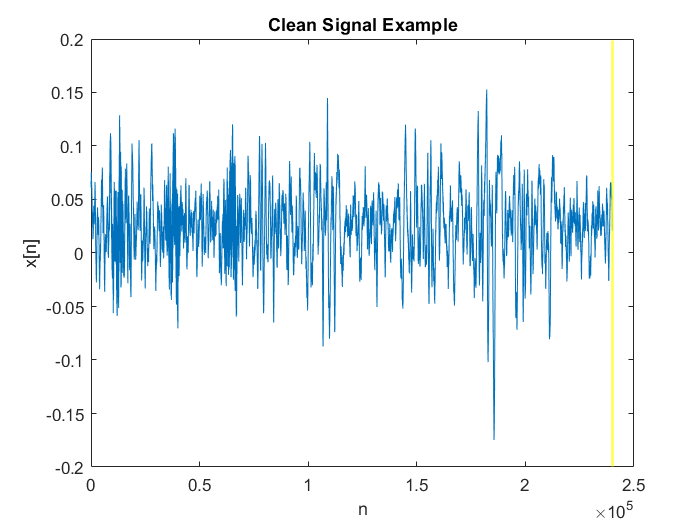

[cleanSig, fs] = audioread('cleanSig.wav');

player2 = audioplayer(cleanSig,fs);
figure
plot(cleanSig)
title('Clean Signal Example')
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player2);
for i = 1:length(cleanSig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

If you look closely, you can see the three quail calls in the beginning of the audio file. And you can definitely hear them much louder while still hearing the same background noise.

In this case, the quails were much closer to the microphone and thats why you can hear and see the calls much clearer.

### Signals in Frequency Domain

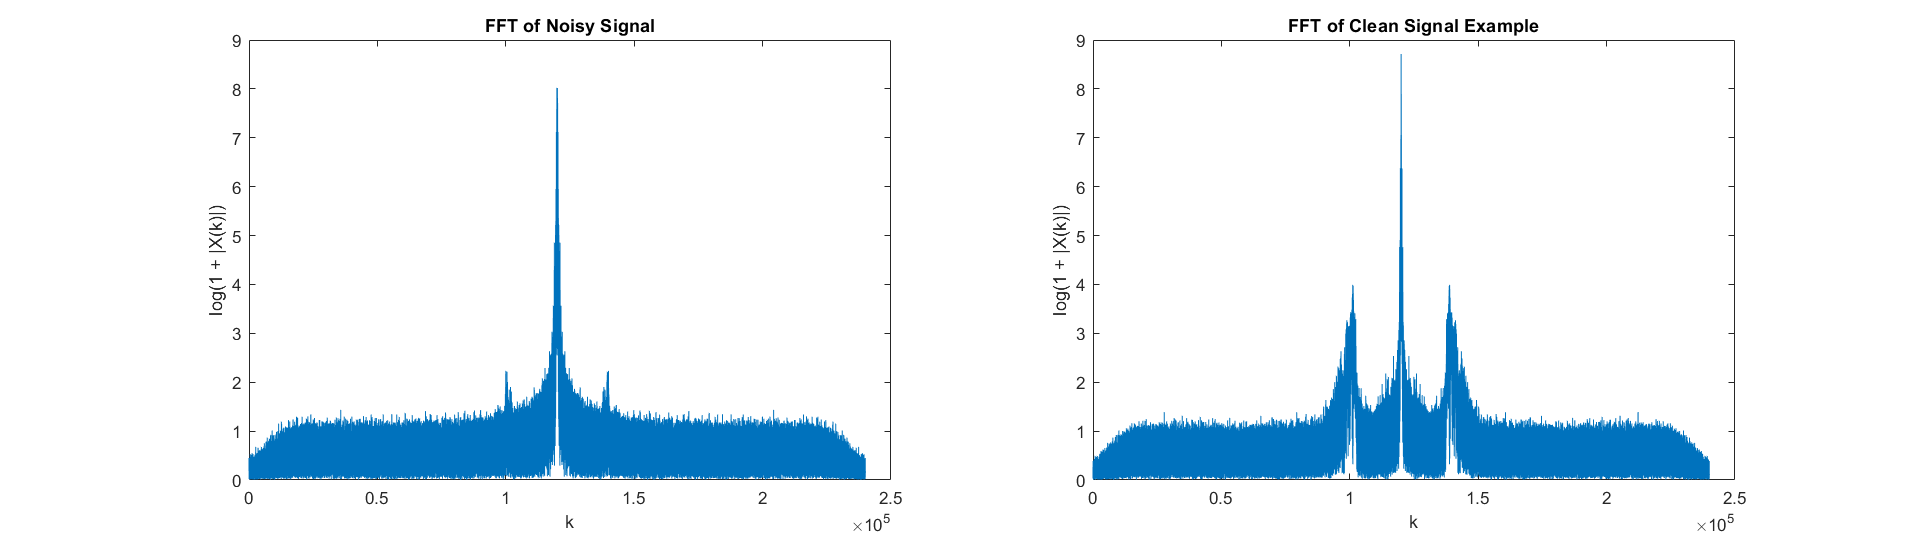

h = figure;
subplot(1,2,1)
noisyFFT = log(1 + abs (fftshift(fft(noisySig))));
plot(noisyFFT)
title('FFT of Noisy Signal');
ylabel('log(1 + |X(k)|)')
xlabel('k');
subplot(1,2,2)
cleanFFT = log(1 + abs (fftshift(fft(cleanSig))));
plot(cleanFFT)
title('FFT of Clean Signal Example');
ylabel('log(1 + |X(k)|)')
xlabel('k');
set(h,'Units','normalized','Position',[0 0 1 .5]); 

The two peaks at the sides of the DC offset are corresponding to the Quail Calls. You can see how the two peaks are having a greater magnitude in the clean signal as the quails were closer to the microphone.

### Quail Call Characteristics

In order to find the bandwidth we started with analyzing the characteristics of the quail calls. Here's an example of a clean quail call:

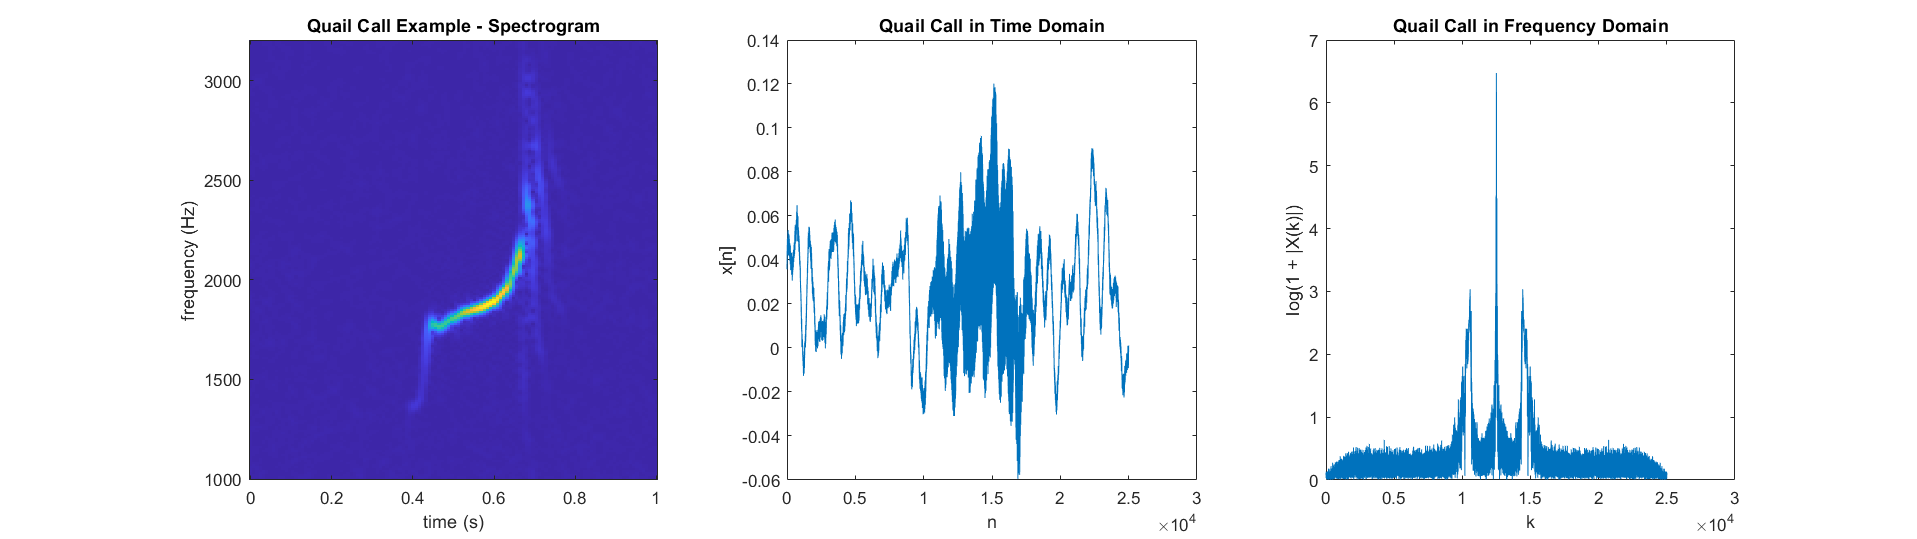

[quailCall, ~] = audioread("quailCall.wav");
h = figure;

subplot(131);
image=spectrogram(quailCall,window,noverlap,F,fs);
imagesc(linspace(0,1,length(F)),F,abs(image))
ylabel('frequency (Hz)')
xlabel('time (s)')
set(gca,'YDir','normal')
title('Quail Call Example - Spectrogram')

subplot(132);
plot(quailCall)
xlabel('n')
ylabel('x[n]')
title('Quail Call in Time Domain')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

subplot(133);
fourierQuail = log(1 + abs (fftshift(fft(quailCall))));
plot(fourierQuail)
ylabel('log(1 + |X(k)|)')
xlabel('k');
title('Quail Call in Frequency Domain')

After inspecting the call in these plots, we concluded that even though the signature of the call is starting anywhere around the 1000-1500 Hz range up to 3200 Hz range, the main part of the call that we would like to preserve after filtering is between 1850 Hz to 2150 Hz. *(The yellow color in the spectrogram - This frequency range is what we hear and recogize as a "Quail Call" when listenning to the audio files)****.***

####  Finding  $f_0$


$$\frac{f_0 }{f_s }=\frac{k}{N}$$


infoQuailCall = audioinfo("quailCall.wav")

infoQuailCall = struct with fields:
             Filename: 'C:\Users\farsh\Documents\MATLAB\DSP\DSP_Part2_FilteringCode\quailCall.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 25001
             Duration: 1.0417
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


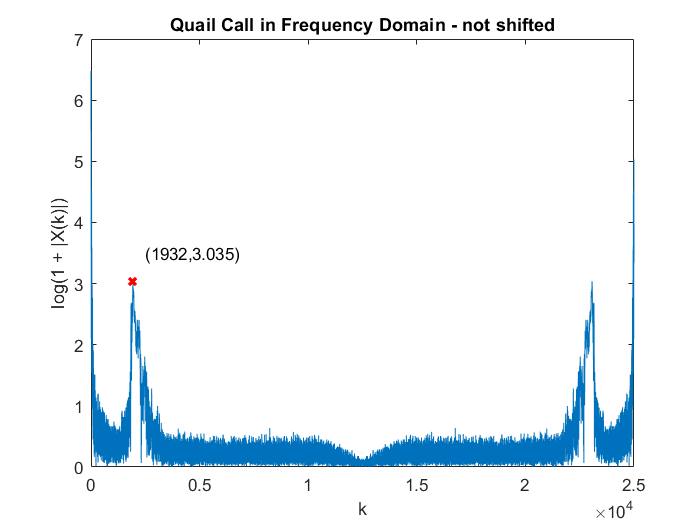

figure
plot(0:length(fourierQuail)-1, ifftshift(fourierQuail))
ylabel('log(1 + |X(k)|)')
xlabel('k');
title('Quail Call in Frequency Domain - not shifted')
hold on
text(2500,3.5,['(' '1932' ',' '3.035' ')'])
plot(1932,3.035,'rx','LineWidth',2)

We can see that our **k = 1932**

f0 = 1932 / infoQuailCall.TotalSamples * fs

f0 = 1.8546e+03


$$f_0 \approx 1855\;\textrm{Hz}$$


This shows that our estimated range of 1850-2150 Hz could be potentially a good bandwidth for our filter.

### Filter Design

We started by designing several filter in the **Filter Designer **app.

The first approach was to design a **Band-pass **filter with the desired bandwidth. After applying our filter to the noisy signal, we reached realtively good results, but the background noise was still prominent with respect to the quail calls.

Then we tried a different approach:

- First we assumed that our noise model is an **Additive Noise Model: **


$$\textrm{Noisy}\;\textrm{Signal}=\textrm{Clean}\;\textrm{Signal}+\textrm{Background}\;\textrm{Noise}$$


- Then, We designed a **Band-stop **filter with the mentiond bandwidth and applied it to our signal $\to$ This will filter out the quail call from our noisy signal and leave us only with the background noise.

- Then, using our noise model assumption, we got our clean signal in the following way:


$$\textrm{Filtered}\;\textrm{Signal}=\textrm{Background}\;\textrm{Noise}$$



$$\Longrightarrow \textrm{Clean}\;\textrm{Signal}=\textrm{Noisy}\;\textrm{Signal}-\textrm{Filtered}\;\textrm{Signal}$$


Here's a demonstration of our work:

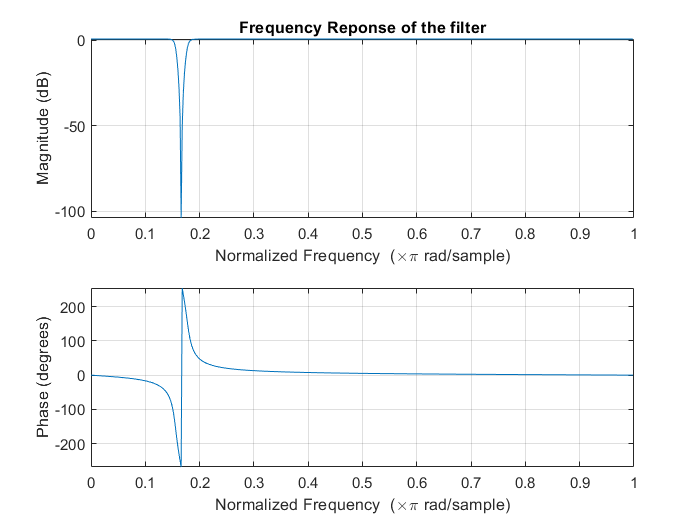

% Loading filter coefficients from the designed filter
load('filterCoefficients.mat')
load('filterObject.mat')
figure
freqz(SOS)
title('Frequency Reponse of the filter')

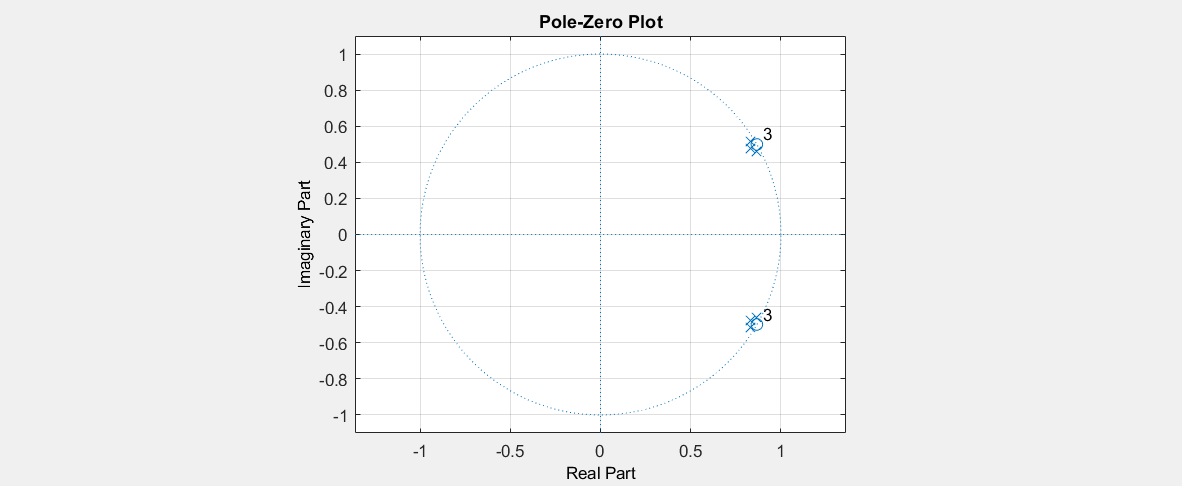

figure
zplane(filterObject)

% Filtering our signal
filteredSig = filter(filterObject, noisySig);

% Subtracting the filtered signal (background noise) from the noisy signal
signal = noisySig - filteredSig;

### Resulting Signal in time Domain

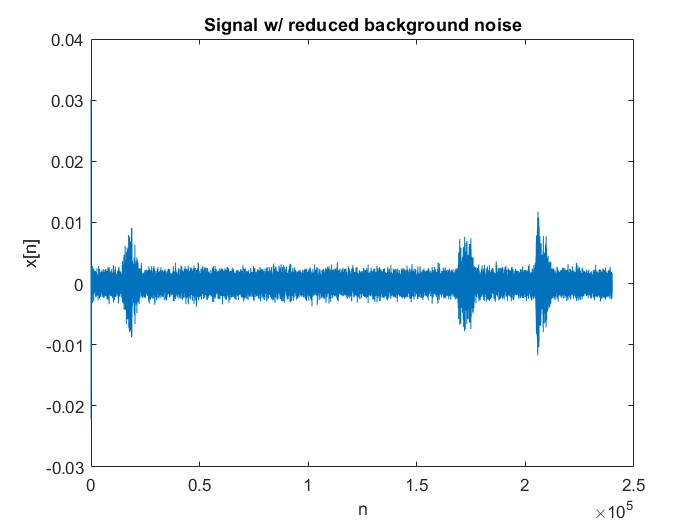

figure
plot(signal)
title('Signal w/ reduced background noise')
xlabel('n')
ylabel('x[n]')

Now we can clearly see the Call signatures in the Time Domain:

Lets listen to the resulting signal:

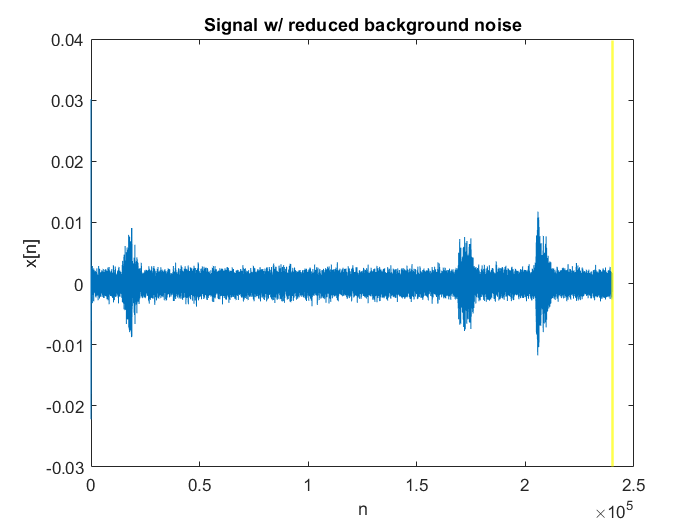

player3 = audioplayer(signal,fs);
figure
plot(signal)
title('Signal w/ reduced background noise')
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player3);
for i = 1:length(signal)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

audiowrite('resultSig.wav', signal, fs)

### Resulting Signal in the Frequency Domain

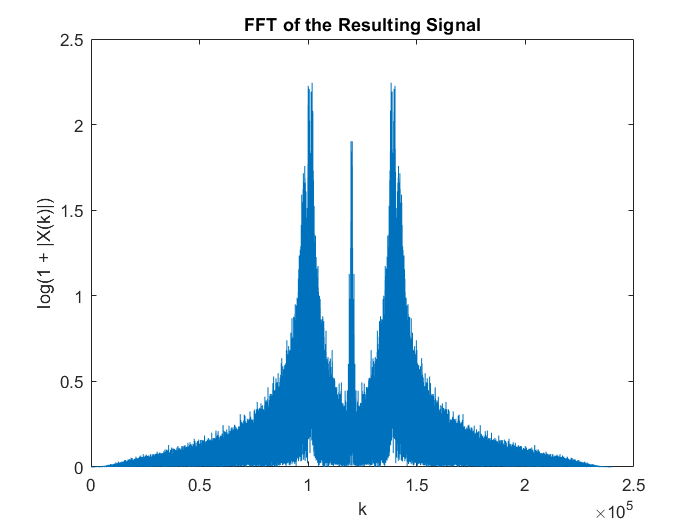

FFT = log(1 + abs (fftshift(fft(signal))));
figure
plot(FFT)
title('FFT of the Resulting Signal');
ylabel('log(1 + |X(k)|)')
xlabel('k');

# Appendix

### Applying the Filter to the Clean Signal Example to reduce the Background Noise

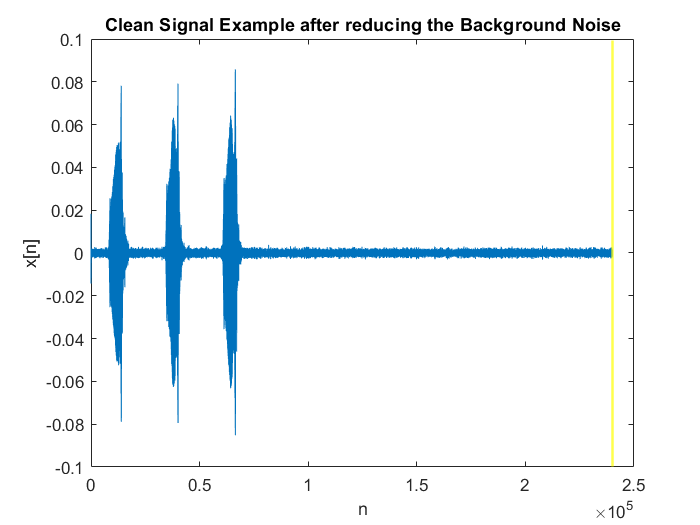

% Filtering
filteredSig2 = filter(filterObject, cleanSig);
signal2 = cleanSig - filteredSig2;

player4 = audioplayer(signal2,fs);
figure
plot(signal2)
xlabel('n')
ylabel('x[n]')
title('Clean Signal Example after reducing the Background Noise')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player4);
for i = 1:length(signal2)/2400 
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

audiowrite('resultSig_cleanSignalExample.wav', signal2, fs);

We can see that, this filter can be applied to all the recordings whether the calls are far or close to the microphone. With this operation, the calls could be easily detected even just by looking at the Time-Domain signal plot.

### Simple Quail Call Detection Algorithm using Local Maxima of the Signal

As shown before, after reducing the noise from the background we can now clearly detect the calls just by inspecting the time-domain signal visually.

We can develop several algorithms to detect these calls which was one of the ultimate goals of this project.

Here's a simple algorithm that can detect these calls just using **Local Maxima:**

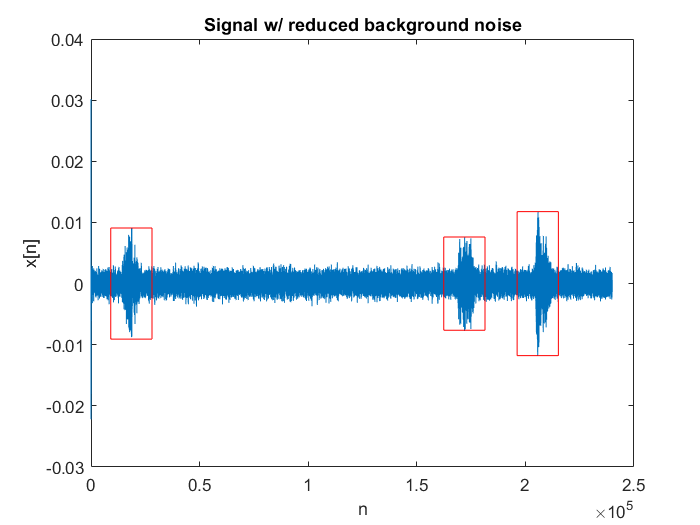

figure
% Detecting Calls using Local Maxima
[pks, locs] = findpeaks(signal(100:end), 'MinPeakProminence',0.01, 'MinPeakDistance', 10000);
plot(signal)
title('Signal w/ reduced background noise')
xlabel('n')
ylabel('x[n]')
for i = 1:length(pks)
    rectangle('Position', [locs(i)-9500 -pks(i) 19000 2*pks(i)], 'EdgeColor', 'r')
end

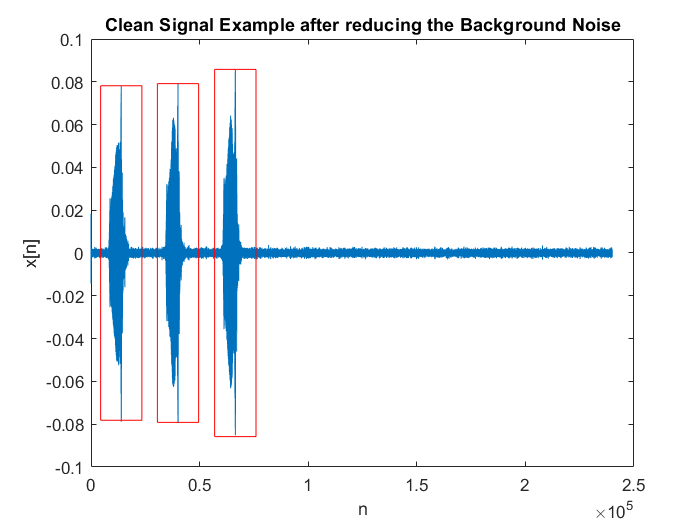

figure
% Detecting Calls using Local Maxima
[pks2, locs2] = findpeaks(signal2, 'MinPeakProminence',0.15, 'MinPeakDistance', 1000);
plot(signal2)
xlabel('n')
ylabel('x[n]')
title('Clean Signal Example after reducing the Background Noise')
for i = 1:length(pks2)
    rectangle('Position', [locs2(i)-9500 -pks2(i) 19000 2*pks2(i)], 'EdgeColor', 'r')
end